# Exercise 2.3 - Generating a periodic signal

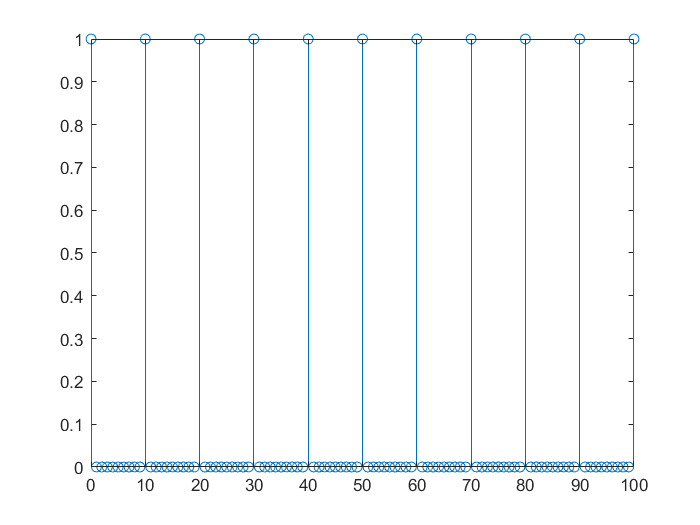

% In this exercise we are going to generate a periodic triangular signal of period N = 10 samples.

% First of all, let's generate a stream of deltas of period N = 10, made
% of 101 samples, (0 ≤ n ≤ 100).
stream = zeros(1, 101);
stream(1 : 10 : 101) = 1;
nstream = 0 : 100;

% Let's plot the result to check for correctness.
stem(nstream, stream)

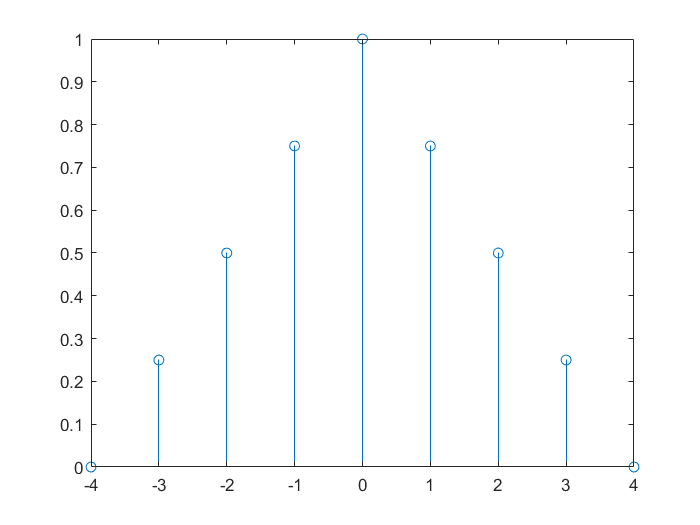


% Next, let's generate a triangular signal made of 7 non-zero samples.
% Again, plot the signal.
tri = [0 triang(7)' 0];
ntri = -4 : 4;
stem(ntri, tri)

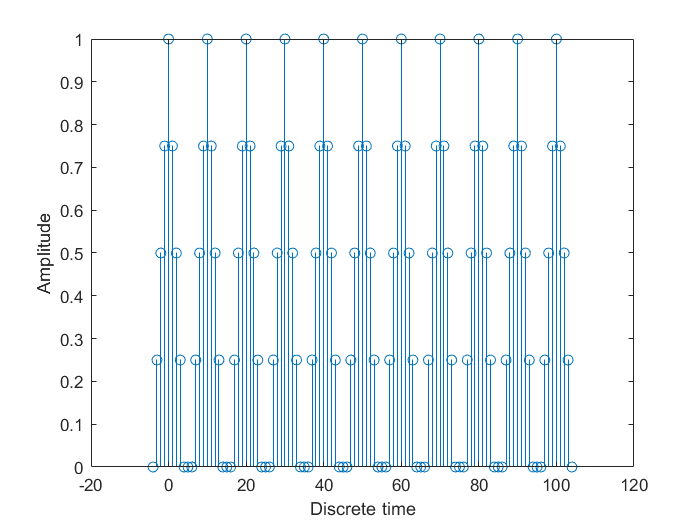


% Finally, we will get the periodic signal by computing the convolution between the stream of deltas 
% and the triangular signal.
y = conv(tri, stream);

% Plot the result of the convolution
ny = -4 : 104;
stem(ny, y)
xlabel('Discrete time'), ylabel('Amplitude')